# Removing Electrical Line Noise

- ac frequency is typically 60hz (some countries 50hz, as in this dataset)

### Load the dataset

load ../datasets/lineNoiseData.mat;
len = length(data);
t = (0:len-1)/srate;

### Compute the power spectrum

power_spectrum = abs(fft(data)/len).^2;
hz = linspace(0,srate,len);

### Plot

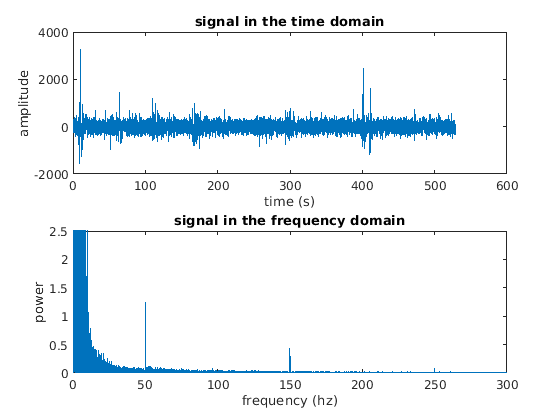

f1 = figure(1); clf;
subplot(211);
plot(t, data);
xlabel("time (s)");
ylabel("amplitude");
title("signal in the time domain");

subplot(212);
plot(hz, power_spectrum);
xlim([0 300]);
ylim([0 2.5]);
xlabel("frequency (hz)");
ylabel("power");
title("signal in the frequency domain");

- note the noise at 50hz, and harmonics (which are not present at all intervals!)

### Filter out the line noise and harmonics

- also plot the kernels

- filtfilt uses reflection and zero phase shift [https://www.mathworks.com/help/signal/ref/filtfilt.html](https://www.mathworks.com/help/signal/ref/filtfilt.html) 

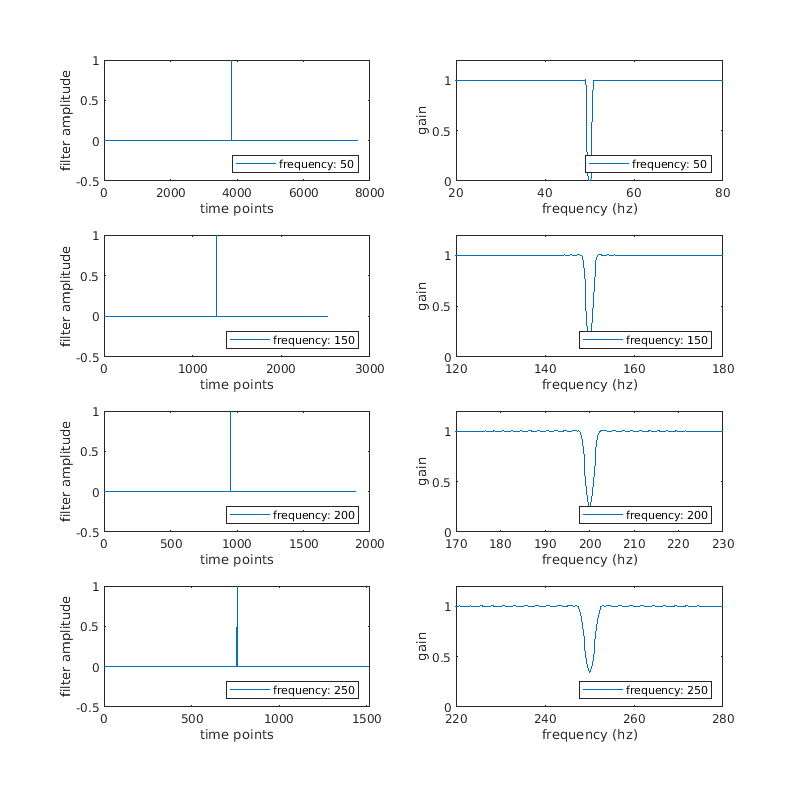

f2 = figure(2); clf;
f2.Position = [0 0 800 800];
freqs = [50 150 200 250];
filtered = data;

for k=1:length(freqs)
    f_range = [freqs(k)-.5 freqs(k)+.5]; % filter out the frequency +/- .5hz
    order = round(200*srate/f_range(1)); % order for the kernel
    kernel = fir1(order, f_range/(srate/2), 'stop'); % kernel using fir1
    filtered = filtfilt(kernel,1,filtered); %apply the filter
    
    %plot the kernels
    f2;
    subplot(4, 2, (k-1)*2+1);
    plot(kernel);
    ylim([-.5 1]);
    xlabel("time points");
    ylabel("filter amplitude");
    legend("frequency: " + num2str(freqs(k)), 'Location', 'SouthEast');
    
    subplot(4, 2, (k-1)*2+2);
    plot(linspace(0,srate,10000), abs(fft(kernel,10000)).^2);
    xlim([freqs(k)-30 freqs(k)+30]);
    ylim([0 1.2]);
    xlabel("frequency (hz)");
    ylabel("gain");
    legend("frequency: " + num2str(freqs(k)), 'Location', 'SouthEast');
end

filter_power = abs(fft(filtered)/len).^2;

### Plot the results

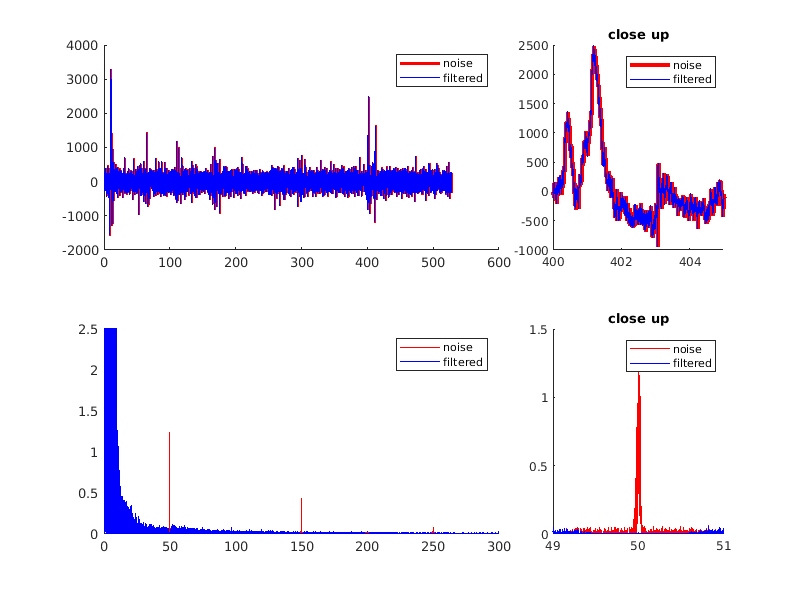

f3 = figure(3); clf;
f3.Position = [0 0 800 600];
subplot(2,3,[1 2]);
hold on;
plot(t, data, 'r', 'linew', 2);
plot(t, filtered, 'b');
hold off;
legend({"noise", "filtered"});

subplot(2,3,3);
hold on;
plot(t, data, 'r', 'linew', 3);
plot(t, filtered, 'b');
hold off;
xlim([400 405]);
legend({"noise", "filtered"});
title("close up");

subplot(2,3,[4 5]);
hold on;
plot(hz, power_spectrum, 'r');
plot(hz, filter_power, 'b');
hold off;
xlim([0 300]);
ylim([0 2.5]);
legend({"noise", "filtered"});

subplot(2,3,6);
hold on;
plot(hz, power_spectrum, 'r');
plot(hz, filter_power, 'b');
hold off;
xlim([49 51]);
ylim([0 1.5]);
legend({"noise", "filtered"});
title("close up");